Numerical Solution of Partial Differential Equations

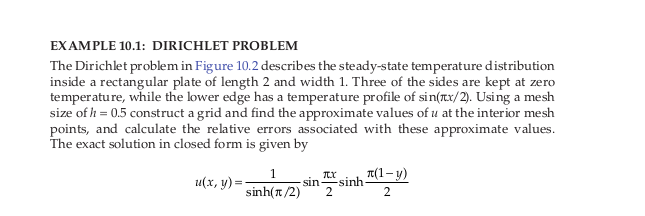

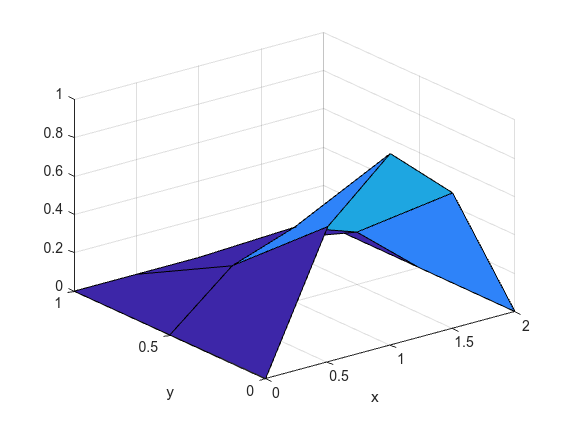

U =                    0                   0                   0                   0                   0
                   0   0.273459080339014   0.386729540169507   0.273459080339014                   0
                   0   0.707106781186547   1.000000000000000   0.707106781186548                   0


x = 0:0.5:2; y = 0:0.5:1;
f = @(x,y)(0); ubottom = @(x)(sin(pi*x/2)); utop = @(x)(0);
uleft = @(y)(0); uright = @(y)(0);
U = DirichletPDE(x,y,f,uleft,uright,ubottom,utop) % 3D plot suppressed

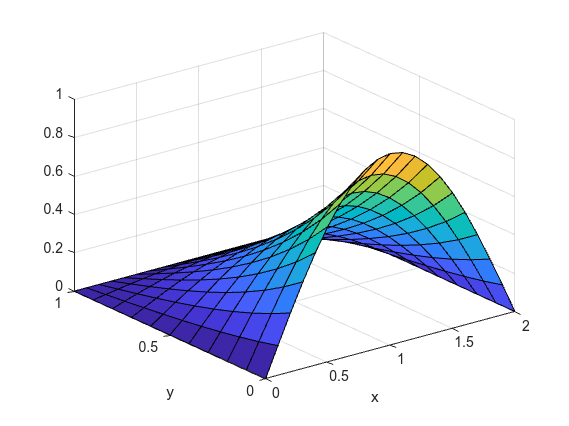

U =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
                   0   0.010737185601671   0.021209986059154   0.031160526267951   0.040343790904175   0.048533657514972   0.055528464403775   0.061155976210551   0.065277624917973   0.067791921855899   0.068636956689244   0.067791921855899   0.065277624917973   0.061155976210551   0.055528464403775   0.048533657514972   0.040343790904175   0.031160526267951   0.021209986059154   0.010737185601671                   0
                   0   0.021738756347532   0.042942232366991   0.063088328108477   0.081680979833776   0.098262374751936   0.112424223889579   0.123817815


x = 0:0.1:2; y = 0:0.1:1;
U = DirichletPDE(x,y,f,uleft,uright,ubottom,utop) % Numerical results suppressed

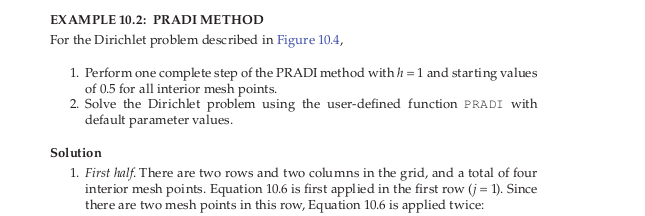

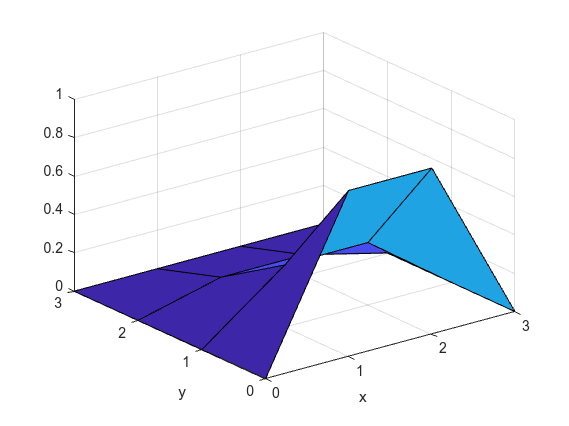

U =                    0                   0                   0                   0
                   0   0.108266865664464   0.108266865664464                   0
                   0   0.324774642166794   0.324774642166794                   0
                   0   0.866025403784439   0.866025403784439                   0


k =      5


clear;clc;
x = 0:1:3; y = 0:1:3; f = @(x,y)(0);
ubottom = @(x)(sin(pi*x/3)); utop = @(x)(0); uleft = @(y)(0);
uright = @(y)(0);
[U, k] = PRADI(x,y,f,uleft,uright,ubottom,utop)

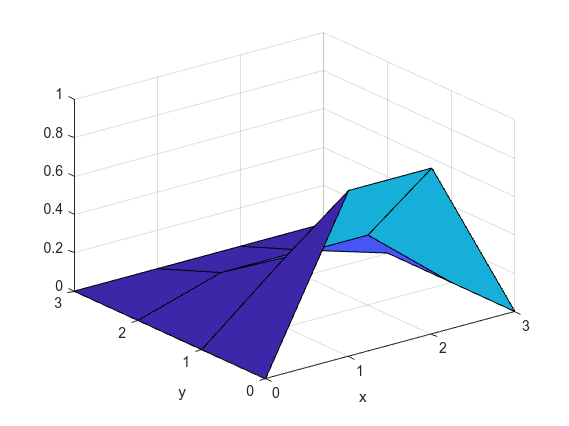

U =                    0                   0                   0                   0
                   0   0.132535591447506   0.132535591447506                   0
                   0   0.363475699123356   0.363475699123356                   0
                   0   0.866025403784439   0.866025403784439                   0



[U] = PRADI(x,y,f,uleft,uright,ubottom,utop,[],1)

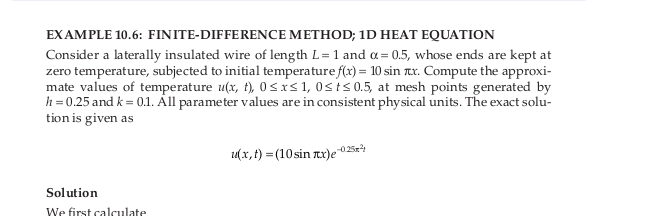

clear;clc;
t = 0:0.1:0.5; x = 0:0.25:1;
u0 = 10.*sin(pi*x);
u = Heat1DFD(t,x,u0,0.5)

u =                    0   1.860959421618578   2.631794053078983   1.860959421618578                   0
                   0   2.430449060385278   3.437174023853806   2.430449060385278                   0
                   0   3.174213562373095   4.489015869776647   3.174213562373095                   0
                   0   4.145584412271571   5.862741699796953   4.145584412271571                   0
                   0   5.414213562373095   7.656854249492380   5.414213562373096                   0
                   0   7.071067811865475  10.000000000000000   7.071067811865476   0.000000000000001


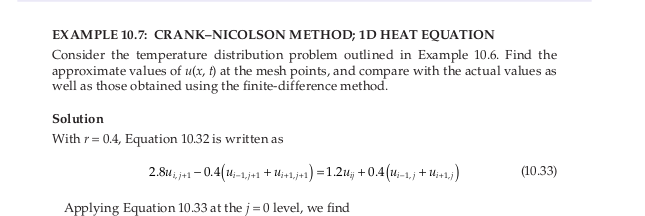

clear;clc;
t = 0:0.1:0.5;
x = 0:0.25:1;
u0 = 10.*sin(pi*x);
u = Heat1DCN(t,x,u0,0.5)

u =                    0   2.179365491405450   3.082088235313493   2.179365491405450                   0
                   0   2.757789135598633   3.900102797728761   2.757789135598633                   0
                   0   3.489731734497278   4.935225947969836   3.489731734497277                   0
                   0   4.415938630534148   6.245080301908665   4.415938630534147                   0
                   0   5.587969354742680   7.902582047602331   5.587969354742679                   0
                   0   7.071067811865475  10.000000000000000   7.071067811865476   0.000000000000001


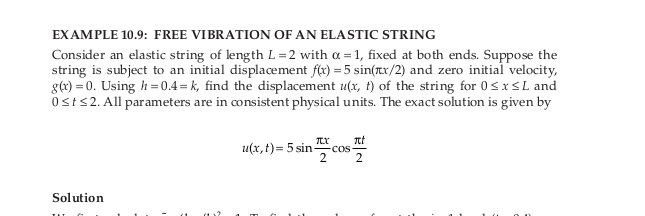

clear;clc;
t = 0:0.4:2; x = 0:0.4:2;
u0 = 5.*sin(pi*x/2); ut0 = zeros(length(x),1);
u = Wave1DFD(t,x,u0,ut0,1)

u =                    0  -2.938926261462366  -4.755282581475768  -4.755282581475768  -2.938926261462366                   0
                   0  -2.377641290737884  -3.847104421469068  -3.847104421469067  -2.377641290737884                   0
                   0  -0.908178160006701  -1.469463130731183  -1.469463130731184  -0.908178160006701                   0
                   0   0.908178160006701   1.469463130731183   1.469463130731183   0.908178160006700                   0
                   0   2.377641290737884   3.847104421469067   3.847104421469067   2.377641290737885                   0
                   0   2.938926261462366   4.755282581475767   4.755282581475768   2.938926261462366   0.000000000000001


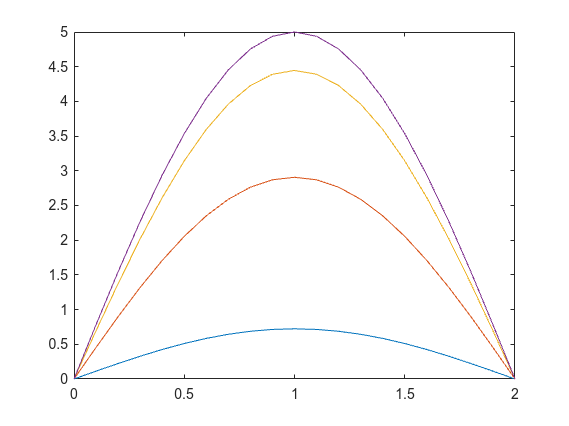


t = 0:0.3:0.9; x = 0:0.1:2;
u0 = 5.*sin(pi*x/2); ut0 = zeros(length(x),1);
u = Wave1DFD(t,x,u0,ut0,1); plot(x,u)